# 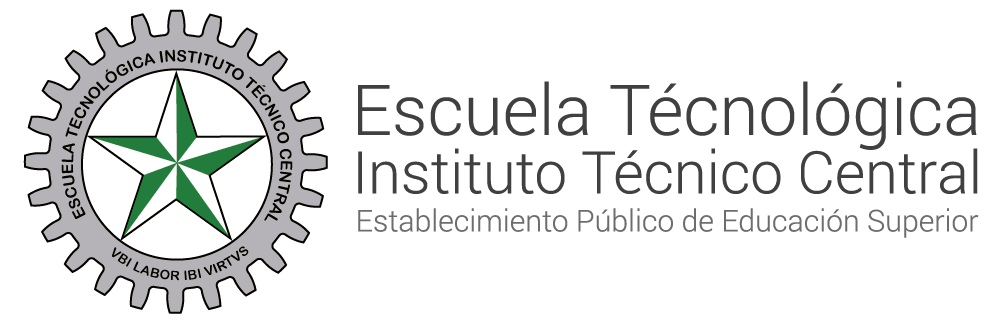

**SISTEMAS DE CONTROL II  **

# **Solución ecuaciones en diferencias**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### CoAutor Darwin Andres Quiroz Macareno. 

#### CoAutor Edward Alejandro Castañeda. 

#### OBJETIVO

Entender y aplicar el concepto de representación de sistemas mediante la transformada Z, y la solución de ecuaciones en diferencias.

Encuentre la transformada z inversas para $y\left(k\right)$ de la siguiente función, aplique fracciones parciales y despues utilice la tabla de transformada Z

                                                                                                                                              
$$y\left\lbrack z\right\rbrack =\frac{10z}{\left(z-1\right)\left(z-0\ldotp 2\right)}$$


#### PASO 1

Aplicamos fraciones parciales a $y\left\lbrack z\right\rbrack$:


$$\frac{10z}{\left(z-1\right)\left(z-0\ldotp 2\right)}=\frac{A}{\left(z-1\right)}+\frac{B}{z-0\ldotp 2}$$
     

Realizamos la suma de las fracciones de la derecha de la igualdad para obtener el mismo denominador en los dos lados.


$$\frac{10z}{\left(z-1\right)\left(z-0\ldotp 2\right)}=\frac{A\left(z-0\ldotp 2\right)+B\left(z-1\right)}{\left(z-1\right)\left(z-02\right)}$$


Se realiza la operación y obtenemos que los denominadores se cancelan. 


$$10z=$$

$$A\left(z-0\ldotp 2\right)+B\left(z-1\right)$$
   

Se desarrolla la multiplicación para obtener los términos en función de z y los términos independientes:


$$10z=\textrm{Az}-0\ldotp 2A+\textrm{Bz}-B$$
 

Agrupamos los términos que contienen z y los términos independientes:


$$10z=z\left(A+B\right)-0\ldotp 2A-B$$


Ahora se igualan los terminos con los factores del lado izquierdo de la ecuación

- términos con $z^1$


$$10=A+B$$


- términos con $z^0$


$$0=-0\ldotp 2A-B$$


Despejamos una de las incognitas en una de las ecuaciones 


$$\begin{array}{l}
A=10-B\;\\
0=-0\ldotp 2\left(10-B\right)-B\\
0=-2+0\ldotp 2B-B\\
2=B\left(0\ldotp 2-1\right)\\
\frac{-2}{0\ldotp 8}=B\;\\
B=-2\ldotp 5
\end{array}$$
         

Ahora que conocemos el valor de $B$ lo sustituimos en la siguiente ecuación          


$$\begin{array}{l}
10=A+B\\
10=A+\left(-2\ldotp 5\right)\\
A=10+2\ldotp 5\\
A=12\ldotp 5
\end{array}$$


Finalmente, reescribimos la ecuación en términos de facciones parciales 


$$\frac{10z}{\left(z-1\right)\left(z-0\ldotp 2\right)}=$$

$$\frac{12\ldotp 5}{\left(z-1\right)}-\frac{2\ldotp 5}{z-0\ldotp 2}$$



$$\frac{10z}{\left(z-1\right)\left(z-0\ldotp 2\right)}=$$

$$12\ldotp 5\frac{1}{\left(z-1\right)}-2\ldotp 5\frac{1}{z-0\ldotp 2}$$


#### **PASO 2: Aplicación de la Transformada Z Inversa**

Aplicamos transformada z inversa usando la tabla 

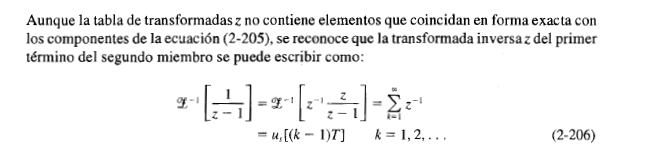


$$12\ldotp 5\frac{1}{\left(z-1\right)}=12\ldotp 5\;u\left\lbrack k-1\right\rbrack$$


para el segundo término tenemos 


$$z^{-1\;} \left(\frac{1}{\left(z-a\right)}\right)=a^k u\left\lbrack k\right\rbrack$$



$$2\ldotp 5\;\frac{1}{z-0\ldotp 2}=-0\ldotp 2^{k\;} u\left\lbrack k\right\rbrack$$


Combinando ambos términos, obtenemos la solución final:


$$y\left\lbrack k\right\rbrack =12\ldotp 5-0\ldotp 2^{k\;}$$


#### **PASO3. Comprobacion con matlab**


$$y\left\lbrack z\right\rbrack =\frac{10z}{\left(z-1\right)\left(z-0\ldotp 2\right)}$$


ingresamos los valores de $y\left\lbrack z\right\rbrack$ para el numerador y para el denominador usamos la la funcion (conv) que realiza la multiplicacion erntre los factores $\left(Z-1\right)$ y $\left(Z-0\ldotp 2\right)$

syms z
numerator = [10 0];
a_0=[1 -1];
a_1=[1 -0.2];
denominator = conv(a_0,a_1);
ts=1;
Y_z = tf(numerator,denominator)


Y_z =
 
        10 s
  -----------------
  s^2 - 1.2 s + 0.2
 
Continuous-time transfer function.
Model Properties


usamos la funcion residue que nos calculara los valores para A y B para las fraciones parciales  

[r,p,k] = residue(numerator,denominator)

r =    12.5000
   -2.5000


p =     1.0000
    0.2000



k =

     []



La documentación de matlab nos dice que la fracción parcial se puede reescribir de la siguiente manera:

Y_z_fract=simplify((r(1)/(1-(p(1)*z^(-1)))))+simplify((r(2)/(1-(p(2)*z^(-1)))))

$$Y\_z\_fract = \frac{25\,z}{2\,\left(z-1\right)}-\frac{25\,z}{10\,z-2}$$

A continuación obtendremos la transformada inversa Z

syms k;
simplify(iztrans(Y_z_fract,z,k))

$$ans = \frac{25}{2}-\frac{5}{2\,5^{k}}$$